# ODE Lab: Creating your own ODE solver in MATLAB

In this lab, you will write your own ODE solver for the Improved Euler method (also known as the Heun method), and compare its results to those of `ode45`.

You will also learn how to write a function in a separate m-file and execute it.

Opening the m-file lab3.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are six (6) exercises in this lab that are to be handed in on the due date. Write your solutions in the template, including appropriate descriptions in each step. Save the .m files and submit them online on Quercus.

## Student Information

Student Name: Jaehah Shin

Student Number: 1008851137

## Creating new functions using m-files.

Create a new function in a separate m-file:

Specifics: Create a text file with the file name f.m with the following lines of code (text):

Now MATLAB can call the new function f (which simply accepts 3 numbers and adds them together). To see how this works, type the following in the matlab command window: sum = f(1,2,3)

% sum = f(1,2,3)

## Exercise 1

Objective: Write your own ODE solver (using the Heun/Improved Euler Method).

Details: This m-file should be a function which accepts as variables (t0,tN,y0,h), where t0 and tN are the start and end points of the interval on which to solve the ODE, y0 is the initial condition of the ODE, and h is the stepsize. You may also want to pass the function into the ODE the way `ode45` does (check lab 2).

% I set the file name as imp_euler.m
% Use for loop to do this. 
% for loop

%function [time,Y] = imp_euler(f, t0, tN, y0, h)
 %   len = round((tN-t0)/h,0);
 %   time = linspace(t0, tN, len);
  %  Y = zeros(1, len);
  %  Y(1) = y0;

%    for i = 2:len
     %   S_L = f(time(i-1), Y(i-1));
     %   S_R = f(time(i), Y(i-1));
     %   improv_slope = (S_L + S_R) / 2;
      %  Y(i) = Y(i -1) + h*improv_slope;
  %  end 

   % plot(time, Y)
  %  title("Exercies 1: ImprovedODE Solver");
   % xlabel("t");
  %  ylabel("y");
    % --> I commented out this part in .m since I realized that it would be
    % better to just plot it explicitly. 
% end


% ODE_solution = imp_euler(f,t0,tN,y0,h);

Note: you will need to use a loop to do this exercise. You will also need to recall the Heun/Improved Euler algorithm learned in lectures. 

## Exercise 2

Objective: Compare Heun with `ode45`.

Specifics: For the following initial-value problems (from lab 2, exercises 1, 4-6), approximate the solutions with your function from exercise 1 (Improved Euler Method). Plot the graphs of your Improved Euler Approximation with the `ode45` approximation.

(a) `y' = y tan t + sin t, y(0) = -1/2` from `t = 0` to `t = pi`

(b) `y' = 1 / y^2 , y(1) = 1` from `t=1` to `t=10`

(c) `y' = 1 - t y / 2, y(0) = -1` from `t=0` to `t=10`

(d) `y' = y^3 - t^2, y(0) = 1` from `t=0` to `t=1`

Comment on any major differences, or the lack thereof. You do not need to reproduce all the code here. Simply make note of any differences for each of the four IVPs.

% (a)
% for ODE45
f_a = @(t,y) y.*tan(t) + sin(t);
% The initial conditions
t0 = 0;
tN = pi;
y0 = -1/2;
sol_by_45 = ode45(f_a, [t0, tN], y0);
% my ODE solver (Improved Euler)
[Imp_x, Imp_y] = lab3_shinja19_imp_euler(f_a, t0,tN,y0,0.001);
subplot(2,2,1);
plot(sol_by_45.x, sol_by_45.y, Imp_x, Imp_y);
legend('ODE45', 'My ODE', 'Location', 'Best');
title("2.a) y' = y*(tan(t))+(sin(t))");
ylabel('y');
xlabel('t');
% For a, which is y' = y tan t + sin t, no major difference is noticed. As
% the graph is shown, other than My ODE line is more smoother than ODE 45,
% the line looks similar from each other. 

% (b)
f_b = @(t,y) 1/(y^2)

f_b = function_handle with value:
    @(t,y)1/(y^2)


t0 = 1;
y0 = 1;
tN = 10;
sol_45 = ode45(f_b, [t0, tN], y0);
[Imp_x, Imp_y] = lab3_shinja19_imp_euler(f_b, t0,tN,y0,0.001);
subplot(2,2,2);
plot(sol_45.x, sol_45.y, Imp_x, Imp_y);
legend('ODE 45', 'My ODE','Location','Best');
title("2.b) y' = 1 / y^2 ")
xlabel('t');
ylabel("y");
% For b, which is y' = 1 / y^2, there was no major difference between my
% ODE and ODE 45. However, as I mentioned in a), My ODE is smoother than
% ODE 45. Specifically, you can see in ODE 45, more larger gap between two
% points can be noticed between 1 and 2.5 

% (c)
f_c = @(t,y) 1-t*y/2;
t0 = 0;
y0 = -1;
tN = 10;
sol45 = ode45(f_c, [t0, tN], y0);
[Imp_x, Imp_y] = lab3_shinja19_imp_euler(f_c, t0,tN,y0,0.001);
subplot(2,2,3)
plot(sol45.x, sol45.y, Imp_x, Imp_y );
xlabel("t");
ylabel("y");
title("2.c)y' = 1 - t y / 2");
legend("ODE45", "My ODE", "Location", "Best");

% For c, this behaves simliar to other graphs too. First of all, ODE 45 and
% MY ODE has simliar solution. However, My ODE is more smoother, and has
% smaller steps comparing to ODE45.


% (d)
f_d = @(t,y) y.^3 -t.^2;
t0 = 0;
y0 = 1;
tN = 1;
so_l45 = ode45(f_d, [t0, tN], y0);

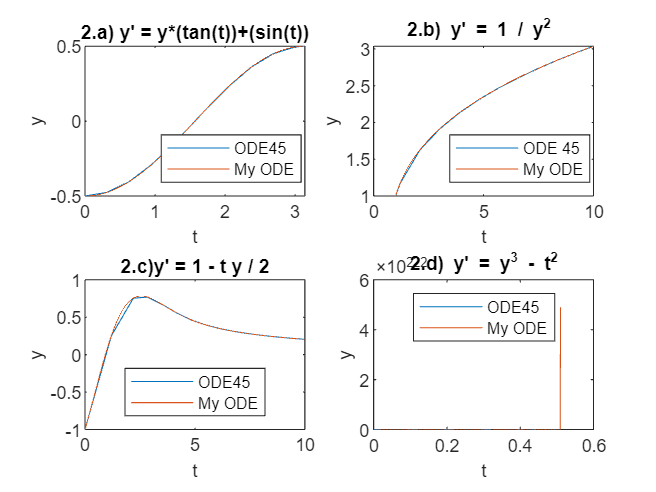

[Imp_x, Imp_y] = lab3_shinja19_imp_euler(f_d, t0,tN,y0,0.001);
subplot(2,2,4)
plot(so_l45.x, so_l45.y, Imp_x, Imp_y);
xlabel("t")
ylabel("y")
title("2.d) y' = y^3 - t^2")
legend("ODE45", "My ODE", "Location", "Best")

% For d, The solution couldn't wasn't able to be plotted in lab 2 when I was using
% ODE 45. when it goes a little bit above 0.5, it goes up to 
% ~10.^22. The orange line which is the solution of My ODE also can't
% compute this integral. Therefore, this indicates they behave similiary.
% (ODE 45 goes up to 10.^7, while My ODE goes to 10.^22)
% Warning: Failure at t=5.066046e-01.  Unable to meet integration tolerances without reducing the step size below the smallest value allowed (1.776357e-15) at time t.

## Exercise 3

Objective: Use Euler's method and verify an estimate for the global error.

Details: 

(a) Use Euler's method (you can use euler.m from iode) to solve the IVP

`y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0`

from `t=0` to `t=0.5`.

xc=euler(@(t,y) 2.*t.*sqrt(1-y.^2) , 0, 0:0.01:0.5);
%function xc=euler(fs,x0,tc);
xc(end)

ans = 0.2427

(b) Calculate the solution of the IVP and evaluate it at `t=0.5`.

% If we solve the ODE, this gives y = sin(t^2 + C)
% As we have initial values, we can just simply compute to evaluate C.
% This will give us C = 0 as initial value is (0,0) 
fprintf('Solution of IVP at t = 0.5 y(0.5): %f. \n', sin(0.5^2));

Solution of IVP at t = 0.5 y(0.5): 0.247404. 


(c) Read the attached derivation of an estimate of the global error for Euler's method. Type out the resulting bound for En here in a comment. Define each variable.

% E_n = (1+M)/2 * dt * M * dt * n
% E_n = error at n
% M = [t0, tN]: there exists an M > 0 so that |f | ≤ M , |∂tf | ≤ M , and |∂yf | ≤ M .
% in this case this is Maximum of f
% dt = h = time = step size which is 0.01 in my case. 
% n = number of steps, = 100 in here
% f = 2 t sqrt( 1 - y^2 )
% ∂tf = 2*sqrt( 1 - y^2 )
% ∂yf = t*(1-y^2)^(-1/2)*(-2y)

t = 0:0.01:0.5;
f = 2.*t.*sqrt(1-xc.^2);
d_tf = 2.*sqrt(1-xc.^2);
d_yf = t.*(1-xc.^2).^(-1/2).*(-2*xc);

max(abs(f));
max(abs(d_tf));
max(abs(d_yf));

M = max(abs(d_tf)) ;
dt = 0.01;
n = 100;
E_n = (1+M)/2 * dt * M * dt * n 

E_n = 0.0300

% resulting bound of error is  ±0.0300

(d) Compute the error estimate for `t=0.5` and compare with the actual error.

fprintf('With a step size of 0.01 and n = 100, the error bound is %f.\n', E_n);

With a step size of 0.01 and n = 100, the error bound is 0.030000.


% fprintf('The actual error computed as %f.\n', abs(xc(end)-y(0.5)));
%error_difference = abs(abs(xc(end)-y(0.5) - E_n));
%fprintf('Error Difference: %f\n', error_difference);

(e) Change the time step and compare the new error estimate with the actual error. Comment on how it confirms the order of Euler's method.

xc=euler(@(t, y) 2*t*sqrt(1-y.^2), 0, 0:0.001:0.5);
t = 0:0.001:0.5;
f = 2.*t.*sqrt(1-xc.^2);
dtf = 2.*sqrt(1-xc.^2);
dyf = t.*(1-xc.^2).^(-1/2).*(-2*xc);

max(abs(f));
max(abs(dtf));
max(abs(dyf));

M = max(abs(dtf));
dt = 0.001;
n = 100;
E_n = (1+M)/2 * dt * M * dt * n

E_n = 3.0000e-04

fprintf('With a step size of 0.001 and n = 100, the error bound is %f.\n', E_n);

With a step size of 0.001 and n = 100, the error bound is 0.000300.


%fprintf('The actual error computed as %f.\n', abs(xc(end)-y(0.5)));


% As euler's method is 1st order, the time step and error should be
% proportional each other. As I did 0.1 of previous one for time step, I
% could see that error bound and actual error also gt 0.1. Therefore, I can
% say that this is first order euler's method. 

## Adaptive Step Size

As mentioned in lab 2, the step size in `ode45` is adapted to a specific error tolerance.

The idea of adaptive step size is to change the step size `h` to a smaller number whenever the derivative of the solution changes quickly. This is done by evaluating f(t,y) and checking how it changes from one iteration to the next.

## Exercise 4

Objective: Create an Adaptive Euler method, with an adaptive step size `h`.

Details: Create an m-file which accepts the variables `(t0,tN,y0,h)`, as in exercise 1, where `h` is an initial step size. You may also want to pass the function into the ODE the way `ode45` does.

Create an implementation of Euler's method by modifying your solution to exercise 1. Change it to include the following:

(a) On each timestep, make two estimates of the value of the solution at the end of the timestep: `Y` from one Euler step of size `h` and `Z` from two successive Euler steps of size `h/2`. The difference in these two values is an estimate for the error.

(b) Let `tol=1e-8` and `D=Z-Y`. If `abs(D)<tol`, declare the step to be successful and set the new solution value to be `Z+D`. This value has local error `O(h^3)`. If `abs(D)>=tol`, reject this step and repeat it with a new step size, from (c).

(c) Update the step size as `h = 0.9*h*min(max(tol/abs(D),0.3),2)`.

Comment on what the formula for updating the step size is attempting to achieve.

% The updated step size is attempting to reduce the step size (h) whenever
% our error is larger than the tolerance. Also, it multiplies by 0.9, so
% that they don't take a too big gap to acheive while getting the smaller
% step size. When the error is under tolerance range, then it won't change
% the step size and keep the step size as it is. This will achieve to the
% more precise while applying smaller step size. This prevents when there
% is higher rate of change, then they can evalute the slope more preciesly.  (with smaller step)

% function [t, y] = lab3_shinja19_adv_eul(f, t0, tN, y0, h)
%     t = [t0];
%     y = [y0];
%     tol = 1e-8;
%     function [Y, Z, D] = helper(y, h, t) % Helperfunction with imp_eulder 
%         Y = y + h * f(t, y);
%         S_L = f(t, y);
%         S_R = f(t + h, Y);
%         improv_slope = (S_L + S_R) / 2;
%         Y = y + h * improv_slope;
% 
%         Z1_first = y + 0.5 * h * f(t, y);
%         S_L = f(t, y);
%         S_R = f(t + 0.5 * h, Z1_first);
%         improved_slope = (S_L + S_R) / 2;
%         Z = Z1_first + 0.5 * h * improved_slope;
% 
%         S_L = f(t + 0.5 * h, Z1_first);
%         S_R = f(t + h, Z1_first);
%         improved_slope = (S_L + S_R) / 2;
%         Z = Z1_first + 0.5 * h * improved_slope;
%         D = Z - Y;
%     end
% 
%     while t(end) < tN
%         [Y, Z, D] = helper(y(end), h, t(end));
%         while abs(D) >= tol % check error range 
%             h = 0.9 * h * min(max(tol / abs(D), 0.3), 2);
%             [Y, Z, D] = helper(y(end), h, t(end));
%         end
%         % Now everything is good 
%         y = [y, Z + D];
%         t = [t, t(end) + h];
%     end
% end

## Exercise 5

Objective: Compare Euler to your Adaptive Euler method.

Details: Consider the IVP from exercise 3.

(a) Use Euler method to approximate the solution from `t=0` to `t=0.75` with `h=0.025`.

xc=euler(@(t, y) 2*t*sqrt(1-y.^2), 0, 0:0.025:0.75);
xc(end)

ans = 0.5193

(b) Use your Adaptive Euler method to approximate the solution from `t=0` to `t=0.75` with initial `h=0.025`.

% My new adavtive 
[t_adapted, y_adapted] = lab3_shinja19_adv_eul(@(t, y) 2*t*sqrt(1-y.^2), 0, 0.75, 0, 0.025);
% results_table = table(t_adapted', y_adapted', 'VariableNames', {'Time', 'Solution'});
% disp(results_table);
% those are just generating my solutions

(c) Plot both approximations together with the exact solution.

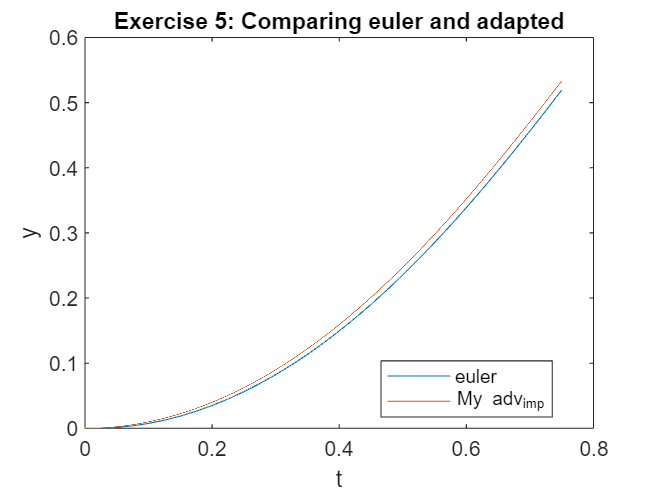

t = 0:0.025:0.75;
figure; 
plot(t, xc , t_adapted, y_adapted);
legend('euler', 'My adv_imp', 'Location', 'Best');
title("Exercise 5: Comparing euler and adapted");
ylabel('y');
xlabel('t');

## Exercise 6

Objective: Problems with Numerical Methods.

Details: Consider the IVP from exercise 3 (and 5).

(a) From the two approximations calculated in exercise 5, which one is closer to the actual solution (done in 3.b)? Explain why.

% The answer I got from 3.b was ans = 0.2427. 
% From the graph, I can tell my ADV_imp was more closer to the acutal
% solution when comparing to euler. The reason behind is ADV_imp method
% takes the error and if the error is tolearnce, then don't change the step
% size, but if error is hihger than tolearnce then it makes smaller step
% size so that it can be under the error tolearnce. That is the reason why
% ADV_imp is closer to the actual solution. 

(b) Plot the exact solution (from exercise 3.b), the Euler's approximation (from exercise 3.a) and the adaptive Euler's approximation (from exercise 5) from `t=0` to `t=1.5`.

xc=euler(@(t, y) 2*t*sqrt(1-y.^2), 0, 0:0.025:1.5);
[t_adapt, y_adapt] = lab3_shinja19_adv_eul(@(t, y) 2*t*sqrt(1-y.^2), 0, 1.5, 0, 0.025);
t = 0:0.025:1.5;
y = @(t) sin(t.^2 + 0);
figure;
plot(t, xc, t_adapt, y_adapt, t, y(t))

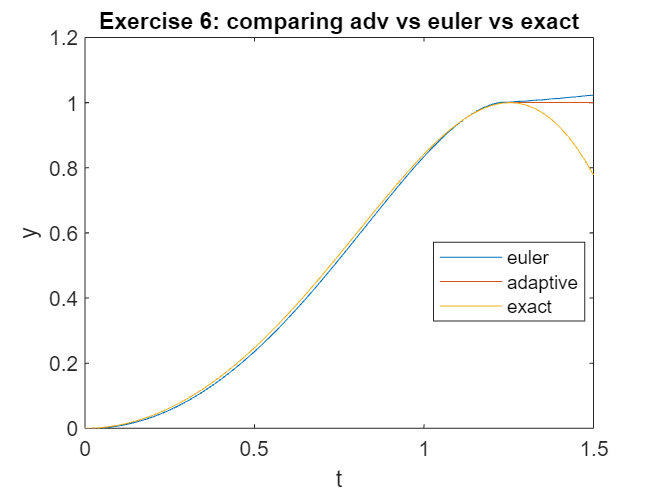

title("Exercise 6: comparing adv vs euler vs exact");
legend("euler", "adaptive", "exact", "Location", "best");
ylabel("y");
xlabel("t");

(c) Notice how the exact solution and the approximations become very different. Why is that? Write your answer as a comment.

% By looking at the graph, we can tell that euler, adaptive, and the exact
% solution acting very very differently around pi/2 (approxiamtely 1.5 when
% assuming pi = 3). 
% Also warning say, imagenry parts of complex X and/ or Y arguments
% ignored. That is because as  y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0, and
% when y is greater than 1, it became imagerny number, therefore, they
% can't handel when y becomes greater than 1. 
% 
% Also, when y is approaching to 1. As we can see from
% the equation 
% (Function is, y' = 2 t sqrt( 1 - y^2 ) , y(0) = 0),
% As our approximation is based on
% y(n+1) = y(n) + h(f(t_n, y(n)) (doesnt matter if we used adaptive or not)
% since governing euler method is same.
% As y(n) = 1, then f will be 0, therefore, this result in y(n+1) = y(n).
% This will result in horizontal slope as shown in euler and adaptvie.
% This is why they can't continue approximate the derivate correctly when they
% reached the point of y' = 0. (due to property of f in our approximation)